fileName = 'DIRECTORY'; % Change this later on
layer = 'block_14_add';

net = mobilenetv2();

data = load('data.mat');
load('classifierABGO.mat');
load('classifierA.mat');
load('classifierG.mat');
load('classifierB.mat');
load('classifierO.mat');

testing_SetABGO = data.testing_Set;
testLabelsABGO = data.testing_Set.Labels;

test_audIMDSABGO = augmentedImageDatastore([224, 224, 3], testing_SetABGO);

featuresTestABGO = activations(net,test_audIMDSABGO,layer);
featuresTestABGO = squeeze(mean(featuresTestABGO,[1 2]))';

[YPredABGO, YCIABGO] = predict(classifierABGO,featuresTestABGO);
accuracyABGO = mean(YPredABGO == testing_SetABGO.Labels)

accuracyABGO = 0.8550

anthroSet = testing_SetABGO.Files(find(YPredABGO == 'anthro'));
bioSet = testing_SetABGO.Files(find(YPredABGO == 'bio'));
geoSet = testing_SetABGO.Files(find(YPredABGO == 'geo'));
otherSet = testing_SetABGO.Files(find(YPredABGO == 'other'));

testing_SetA = testAnthro(anthroSet, 1);
testLabelsA = testing_SetA.Labels;

test_audIMDSA = augmentedImageDatastore([224, 224, 3], testing_SetA);

featuresTestA = activations(net,test_audIMDSA,layer);
featuresTestA = squeeze(mean(featuresTestA,[1 2]))';

[YPredA, YCIA] = predict(classifierA, featuresTestA);
accuracyA = mean(YPredA == testing_SetA.Labels)

accuracyA = 1

testing_SetB = testBio(bioSet, 1);
testLabelsB = testing_SetB.Labels;

test_audIMDSB = augmentedImageDatastore([224, 224, 3], testing_SetB);

featuresTestB = activations(net, test_audIMDSB,layer);
featuresTestB = squeeze(mean(featuresTestB,[1 2]))';

[YPredB, YCIB] = predict(classifierB, featuresTestB);
accuracyB = mean(YPredB == testing_SetB.Labels)

accuracyB = 1

testing_SetG = testGeo(geoSet, 1);
testLabelsG = testing_SetG.Labels;

test_audIMDSG = augmentedImageDatastore([224, 224, 3], testing_SetG);

featuresTestG = activations(net, test_audIMDSG,layer);
featuresTestG = squeeze(mean(featuresTestG,[1 2]))';

[YPredG, YCIG] = predict(classifierG, featuresTestG);
accuracyG = mean(YPredG == testing_SetG.Labels)

accuracyG = 1

testing_SetO = testOther(otherSet, 1);
testLabelsO = testing_SetO.Labels;

test_audIMDSO = augmentedImageDatastore([224, 224, 3], testing_SetO);

featuresTestO = activations(net, test_audIMDSO,layer);
featuresTestO = squeeze(mean(featuresTestO,[1 2]))';

[YPredO, YCIO] = predict(classifierO, featuresTestO);
accuracyO = mean(YPredO == testing_SetO.Labels)

accuracyO = 1

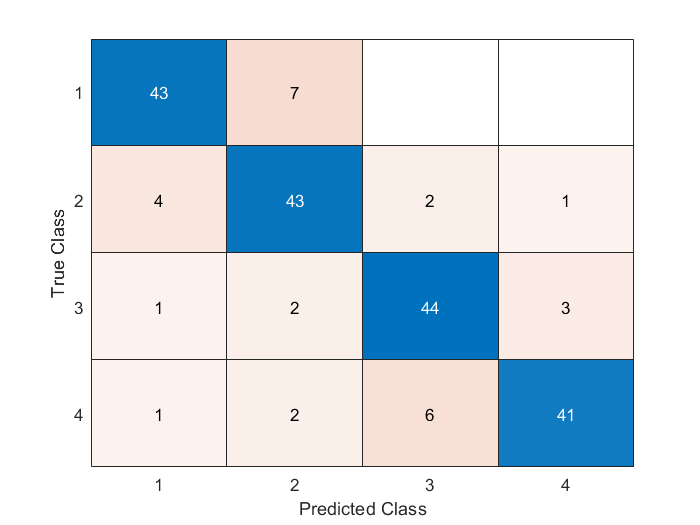

conf_ABGO = confusionmat(testLabelsABGO, YPredABGO);
confusionchart(conf_ABGO);

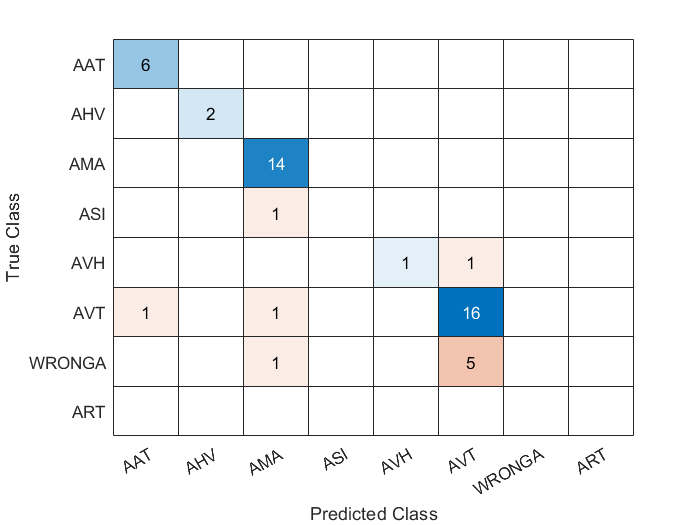


testLabelsA = removecats(testLabelsA, {'anthro' 'bio' 'geo' 'other'});
testLabelsB = removecats(testLabelsB, {'anthro' 'bio' 'geo' 'other'});
testLabelsG = removecats(testLabelsG, {'antrho' 'bio' 'geo' 'other'});
testLabelsO = removecats(testLabelsO, {'anthro' 'bio' 'geo' 'other'});

[conf_A, cm_Labels_A] = confusionmat(testLabelsA, YPredA);
confusionchart(conf_A, cm_Labels_A);

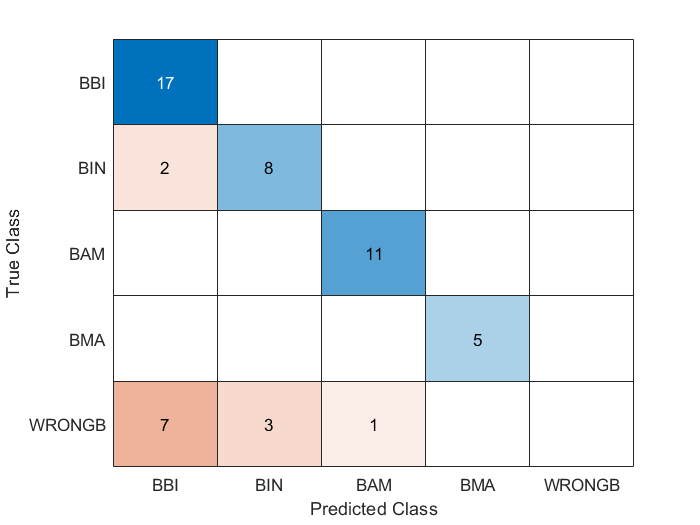


[conf_B, cm_Labels_B] = confusionmat(testLabelsB, YPredB);
confusionchart(conf_B, cm_Labels_B);

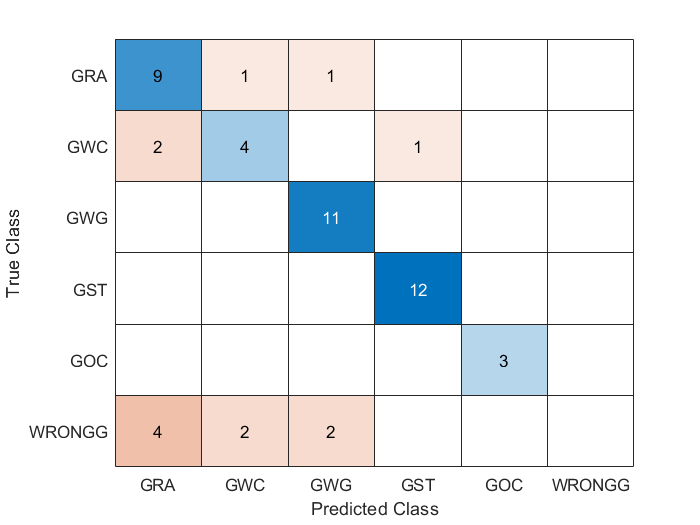


[conf_G, cm_Labels_C] = confusionmat(testLabelsG, YPredG);
confusionchart(conf_G, cm_Labels_C);

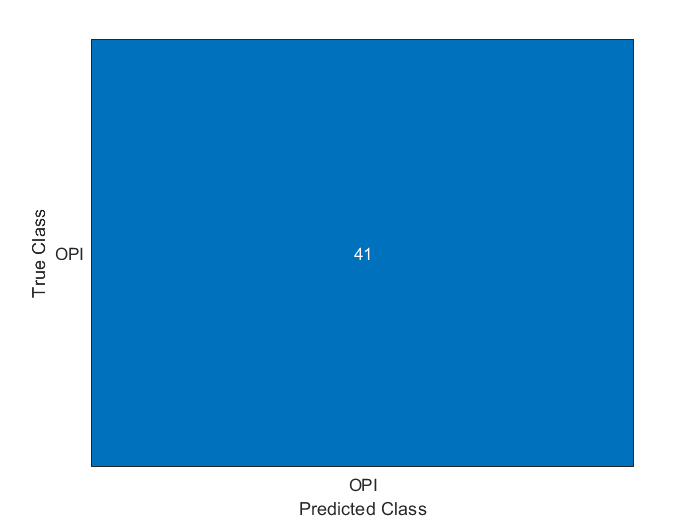


[conf_O, cm_Labels_O] = confusionmat(testLabelsO, YPredO);
confusionchart(conf_O, cm_Labels_O);

ABGOThresholdIndex = [];
AThresholdIndex = [];
BThresholdIndex = [];
GThresholdIndex = [];
OThresholdIndex = [];

for i = 1:length(YCIABGO)
    
    if(any(YCIABGO(i,:) == 0))
        
        ABGOThresholdIndex = [ABGOThresholdIndex;i];
        
    end
    
    
end

accuracyThresholdABGO = mean(YPredABGO(ABGOThresholdIndex) == testing_SetABGO.Labels(ABGOThresholdIndex))

accuracyThresholdABGO = 0.9559


for i = 1:length(YCIA)
    
    if(any(YCIA(i,:) == 0))
        
        AThresholdIndex = [AThresholdIndex;i];
        
    end
    
    
end

accuracyThresholdA = mean(YPredA(AThresholdIndex) == testing_SetA.Labels(AThresholdIndex))

accuracyThresholdA = 0.8667


for i = 1:length(YCIB)
    
    if(any(YCIB(i,:) == 0))
        
        BThresholdIndex = [BThresholdIndex;i];
        
    end
    
    
end

accuracyThresholdB = mean(YPredB(BThresholdIndex) == testing_SetB.Labels(BThresholdIndex))

accuracyThresholdB = 0.8889


for i = 1:length(YCIG)
    
    if(any(YCIG(i,:) == 0))
        
        GThresholdIndex = [GThresholdIndex;i];
       
    end
    
    
end

accuracyThresholdG = mean(YPredG(GThresholdIndex) == testing_SetG.Labels(GThresholdIndex))

accuracyThresholdG = 1


for i = 1:length(YCIO)
    
    if(any(YCIO(i,:) == 0))
        
        OThresholdIndex = [OThresholdIndex;i];
        
    end
    
    
end

accuracyThresholdO = mean(YPredO(OThresholdIndex) == testing_SetO.Labels(OThresholdIndex))

accuracyThresholdO = 0.9111

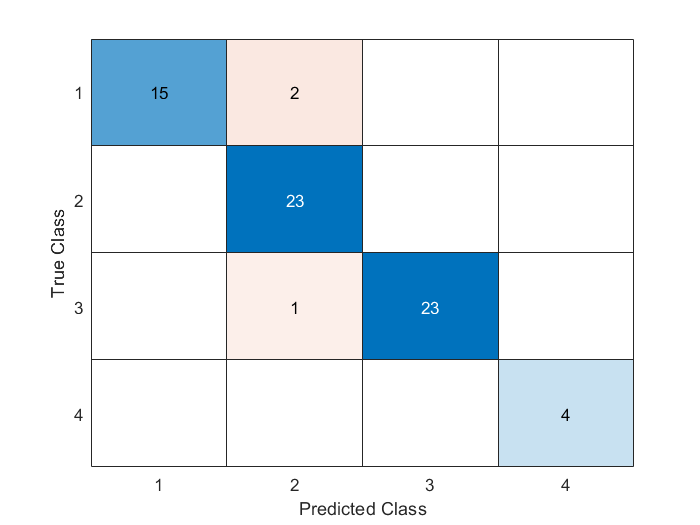

conf_ABGO = confusionmat(testLabelsABGO(ABGOThresholdIndex), YPredABGO(ABGOThresholdIndex));
confusionchart(conf_ABGO);

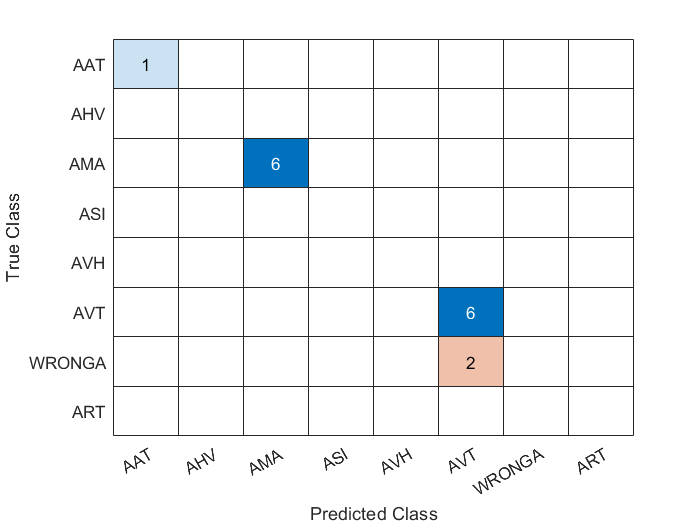


testLabelsA = removecats(testLabelsA, {'anthro' 'bio' 'geo' 'other'});
testLabelsB = removecats(testLabelsB, {'anthro' 'bio' 'geo' 'other'});
testLabelsG = removecats(testLabelsG, {'antrho' 'bio' 'geo' 'other'});
testLabelsO = removecats(testLabelsO, {'anthro' 'bio' 'geo' 'other'});

[conf_A, cm_Labels_A] = confusionmat(testLabelsA(AThresholdIndex), YPredA(AThresholdIndex));
confusionchart(conf_A, cm_Labels_A);

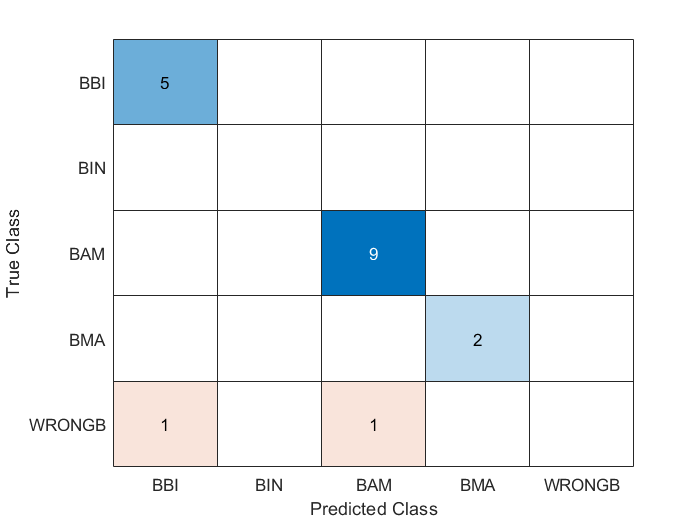


[conf_B, cm_Labels_B] = confusionmat(testLabelsB(BThresholdIndex), YPredB(BThresholdIndex));
confusionchart(conf_B, cm_Labels_B);

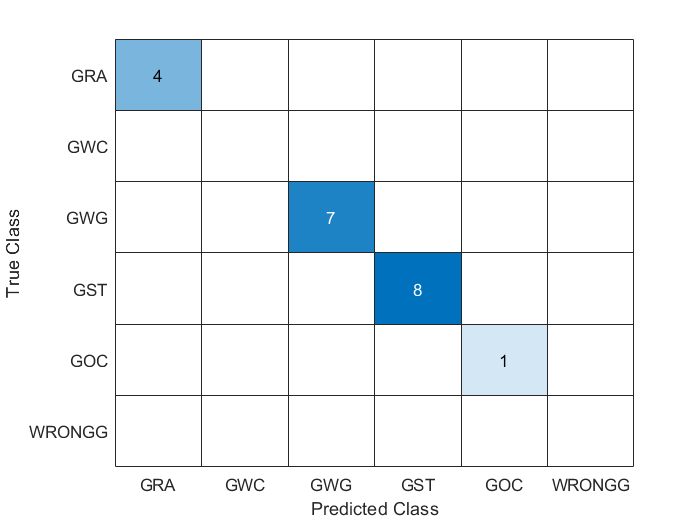


[conf_G, cm_Labels_C] = confusionmat(testLabelsG(GThresholdIndex), YPredG(GThresholdIndex));
confusionchart(conf_G, cm_Labels_C);


[conf_O, cm_Labels_O] = confusionmat(testLabelsO(OThresholdIndex), YPredO(OThresholdIndex));
confusionchart(conf_O, cm_Labels_O);